%f = 40
f = 2030

f = 2030

w = 2 * pi * f;
T = 1/f

T = 4.9261e-04


point_distance = 0.01; %in m

c = 343.3 %in m/s

c = 343.3000

loss_per_distance = -3 % in dB

loss_per_distance = -3


lambda = c / f % in m

lambda = 0.1691


k = 2 * pi / lambda

k = 37.1537


N_hor = 600;
N_ver = N_hor;

% array_start = N_ver * 1/3;
% array_end = N_ver * 2/3;
% array_length = array_end - array_start;
% array_length_m = point_distance * array_length
% 
% No_linearray_elements = 6
% points_per_element = round(array_length / No_linearray_elements);

array_length_m = 1.28

array_length_m = 1.2800

array_length = round(array_length_m / point_distance)

array_length = 128

No_linearray_elements = 6

No_linearray_elements = 6

points_per_element = round(array_length / No_linearray_elements);
array_start = round((N_ver - array_length) / 2);
array_end = round((N_ver + array_length) / 2);

t_start = 0

t_start = 0

t_end = 0.001

t_end = 1.0000e-03


array_frequency = c / array_length_m

array_frequency = 268.2031

ratio_arrarylenth_lambda = array_length_m / lambda

ratio_arrarylenth_lambda = 7.5689

ratio_arraryelementlenth_lambda = array_length_m / No_linearray_elements / lambda

ratio_arraryelementlenth_lambda = 1.2615

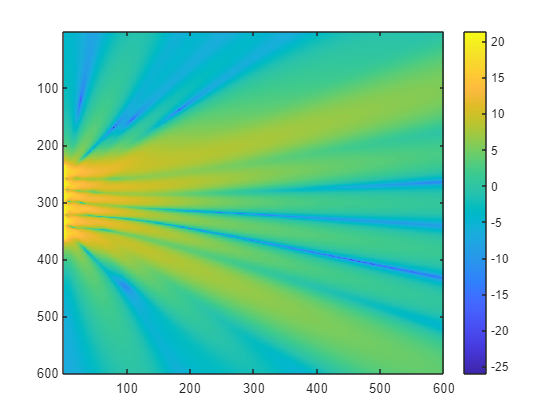


d_t = (t_end - t_start) / (No_linearray_elements - 1);

pressure_field = zeros(N_hor, N_ver);
delay_times = zeros(N_ver, 1);

for a = 1:1:No_linearray_elements
    %delay_times(i) = t_start + round(i/points_per_element) * d_t;
    for dy = 1:1:points_per_element
        delay_times((a - 1) * points_per_element + dy + array_start) = (a - 1) * d_t;
    end
end

delay_times;

for y = 1:1:N_ver
    for x = 1:1:N_hor
        pressure = 0;
        for source = array_start:4:array_end
            delta_x = x - 1;
            delta_y = y - source;
            distance = sqrt(delta_x^2 + delta_y^2) * point_distance;
            time = delay_times(source,1);
            pressure = pressure + exp(1i * (w * time - distance * k)) / distance;
        end
        pressure_field(y,x) = 10 * log10(abs(pressure));
    end
end

imagesc(pressure_field)
colorbar


%imagesc(spl_field)
%colorbar